# [3.11. Электрическая цепь](https://ru.wikipedia.org/wiki/%D0%AD%D0%BB%D0%B5%D0%BA%D1%82%D1%80%D0%B8%D1%87%D0%B5%D1%81%D0%BA%D0%B0%D1%8F_%D1%86%D0%B5%D0%BF%D1%8C)

#### [Закон Ома](https://ru.wikipedia.org/wiki/Закон_Ома)

clear
syms V R I j sigma E
V==R*E

$$ans = V=\text{E}\,R$$

j==sigma*E

$$ans = j=\text{E}\,\sigma$$

#### Электропроводность проведения

syms sigma L R A
sigma==L/(R*A)

$$ans = \sigma =\frac{L}{A\,R}$$

% L = длина проводника
% A = площадь сечения

#### [Удельное сопротивление](https://ru.wikipedia.org/wiki/Удельное_электрическое_сопротивление) и [электрическая проводимость](https://ru.wikipedia.org/wiki/Электропроводность)

syms rho R A sigma L G
rho==(1/rho)*R*A/L

$$ans = \rho =\frac{A\,R}{L\,\rho }$$

G==1/R

$$ans = G=\frac{1}{R}$$

#### Температурная зависимость сопротивления

syms rho rho0 alpha T T0
rho==rho0*(1+alpha*(T-T0))

$$ans = \rho =\rho_{0}\,\left(\alpha \,\left(T-T_{0}\right)+1\right)$$

% alpha = температурный коэффициент
% T = температура

#### Общее сопротивление для последовательного и параллельного соединений резисторов

syms R_s R(n) R_p
R_s==symsum(R(n))         % последовательное соединение

$$ans = R_{s}=\sum_{n}R\left(n\right)$$

1/R_p==symsum(1/R(n))     % параллельное соединение

$$ans = \frac{1}{R_{p}}=\sum_{n}\frac{1}{R\left(n\right)}$$

В частности, два параллельных резистора

syms R1 R2
R_p==(R1*R2)/(R1+R2)

$$ans = R_{p}=\frac{R_{1}\,R_{2}}{R_{1}+R_{2}}$$

Это же правило действует и для импеданса Z в случае последовательного и параллельных соединений

#### Деление напряжений

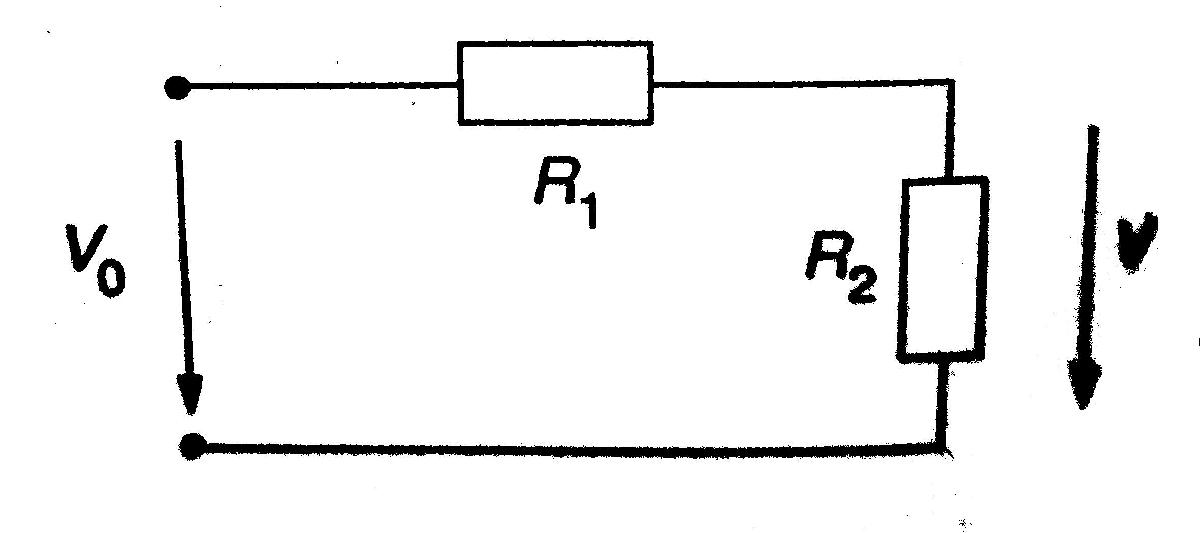

syms V0 V2 R1 R2
V2==R2/(R1+R2)*V0

$$ans = V_{2}=\frac{R_{2}\,V_{0}}{R_{1}+R_{2}}$$

#### 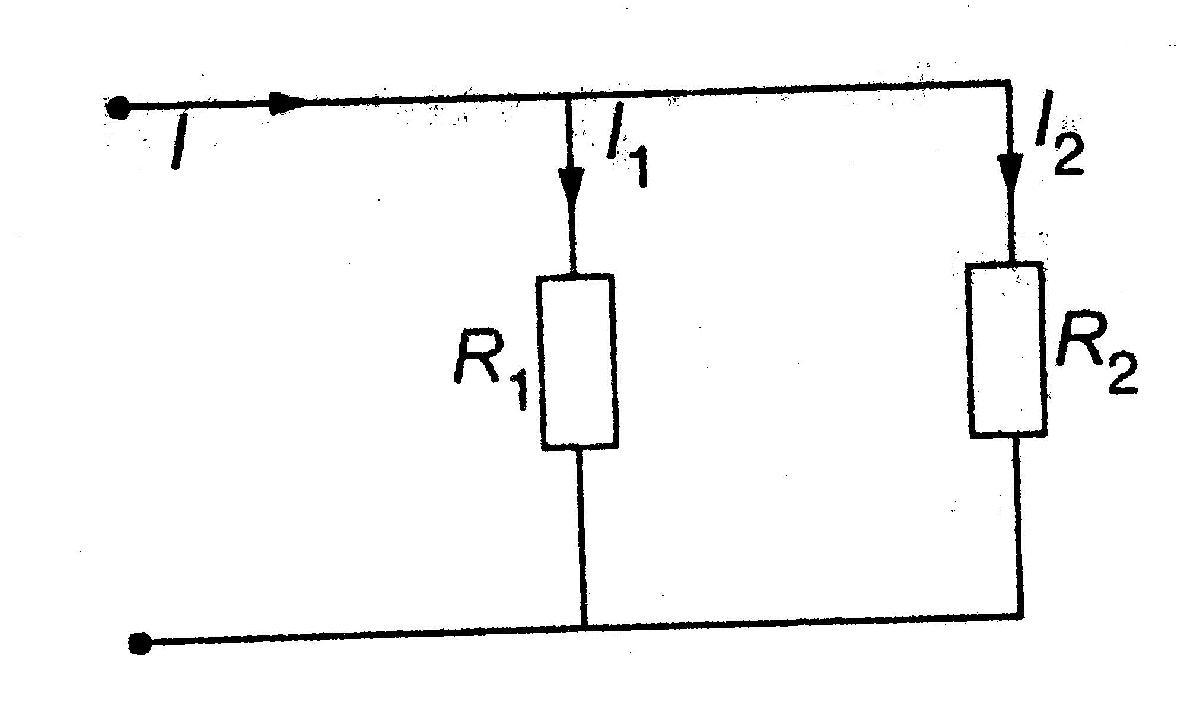

#### Деление токов

syms I1 I2 
I2==(R1/(R1+R2))*I

$$ans = I_{2}=\frac{\text{I}\,R_{1}}{R_{1}+R_{2}}$$

#### [Правила Кирхгофа](https://ru.wikipedia.org/wiki/%D0%9F%D1%80%D0%B0%D0%B2%D0%B8%D0%BB%D0%B0_%D0%9A%D0%B8%D1%80%D1%85%D0%B3%D0%BE%D1%84%D0%B0)

syms I(i) V(i)
symsum(I(i))==0     % для узла

$$ans = \sum_{i}\text{I}\left(i\right)=0$$

symsum(V(i))==0     % по замкнутой цепи

$$ans = \sum_{i}V\left(i\right)=0$$

#### Закон Джоуля для тепловой энергии

syms P V I R 
P==V*I==R*I^2==V^2/R

$$ans = \left(\left(P=\text{I}\,V\right)={\text{I}}^{2}\,R\right)=\frac{V^{2}}{R}$$

#### Преобразование между Y- и дельта-образными соединениями

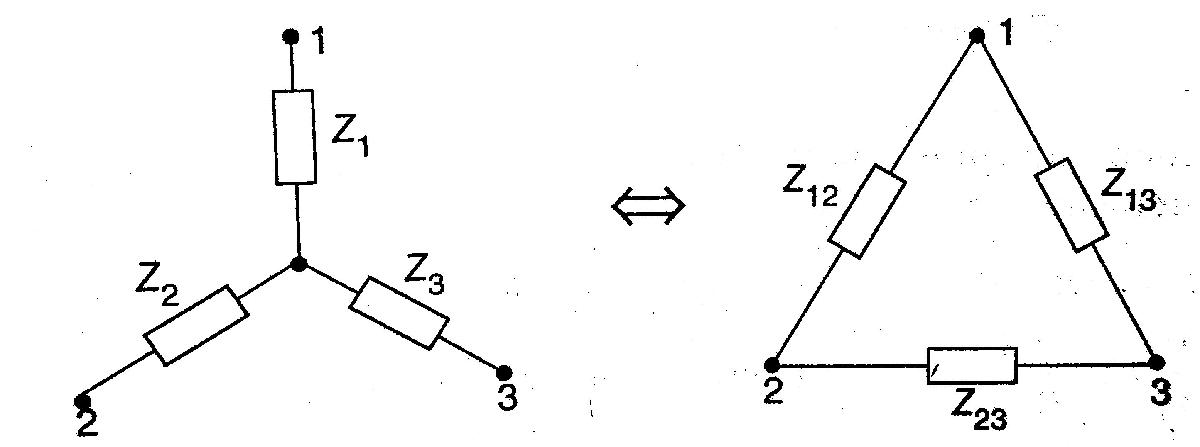

syms Z1 Z2 Z3 Z12 Z23 Z13
Z1==(Z12*Z13)/(Z12+Z13+Z23)

$$ans = Z_{1}=\frac{Z_{12}\,Z_{13}}{Z_{12}+Z_{13}+Z_{23}}$$

Z12==Z1*Z2*(1/Z1+1/Z2+1/Z3)

$$ans = Z_{12}=Z_{1}\,Z_{2}\,\left(\frac{1}{Z_{1}}+\frac{1}{Z_{2}}+\frac{1}{Z_{3}}\right)$$

#### Эквивалентная схема Тевнина для активного двухполюсника

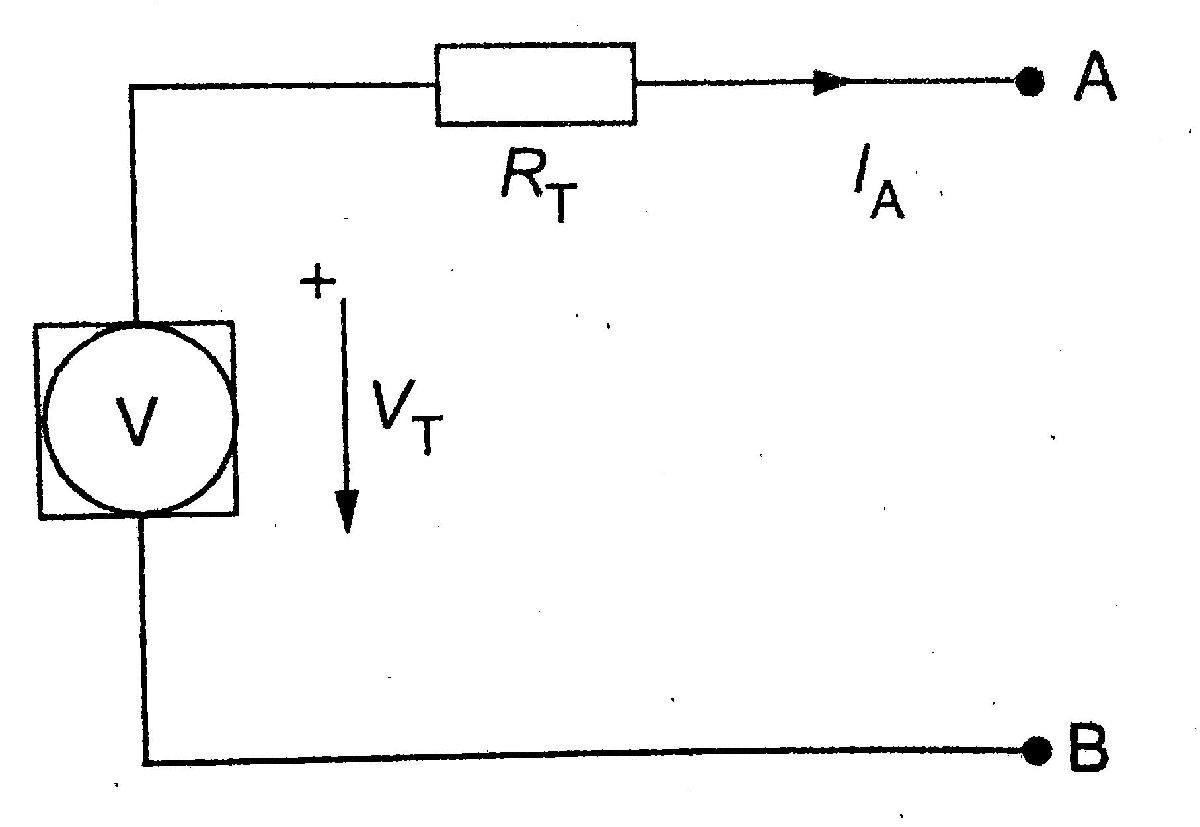

% V_T = разность потенциалов в открытом контуре между A и B (I_A=0)
% R_T = сопротивление между A и B, если все источники напряжения
% закорочены и все источники тока неактивны.

#### Эквивалент Нортона для активного двухполюсника

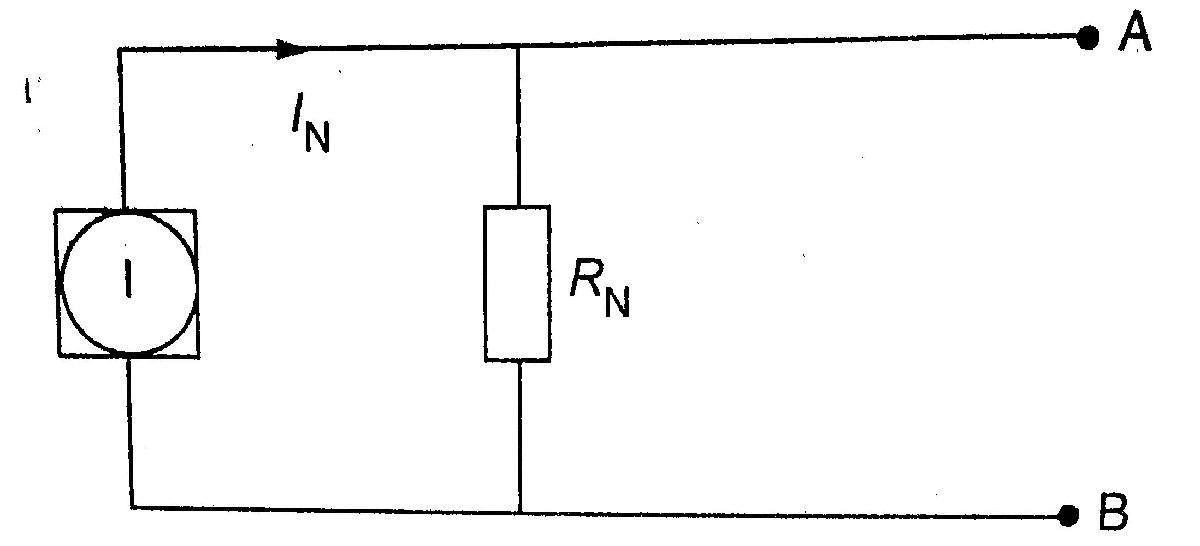

% I_N = ток, текущий через A-B, если выход закорочен
syms R_N R_T
R_N==R_T

$$ans = R_{N}=R_{T}$$

#### Теорема обратимости для пассивной цепи

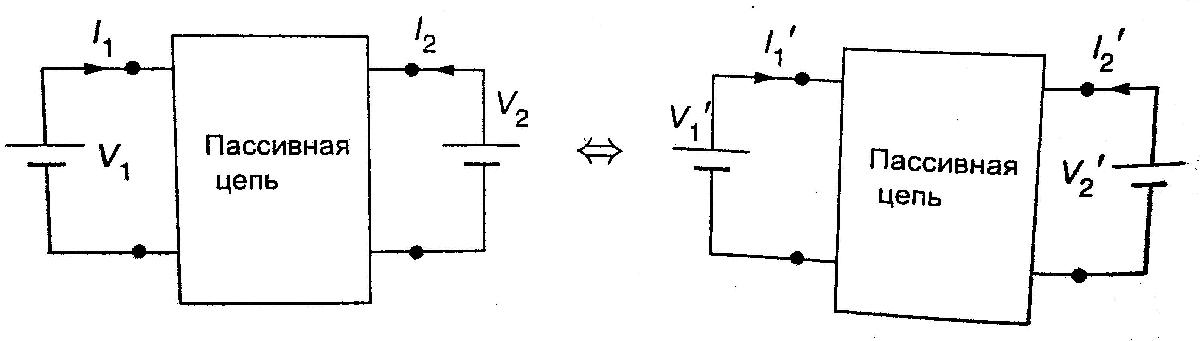

syms V1 I11 V2 I21 V11 I1 V21 I2
V1*I11+V2*I21==V11*I1+V21*I2

$$ans = I_{11}\,V_{1}+I_{21}\,V_{2}=I_{1}\,V_{11}+I_{2}\,V_{21}$$

#### Теорема Миллера

**I.**

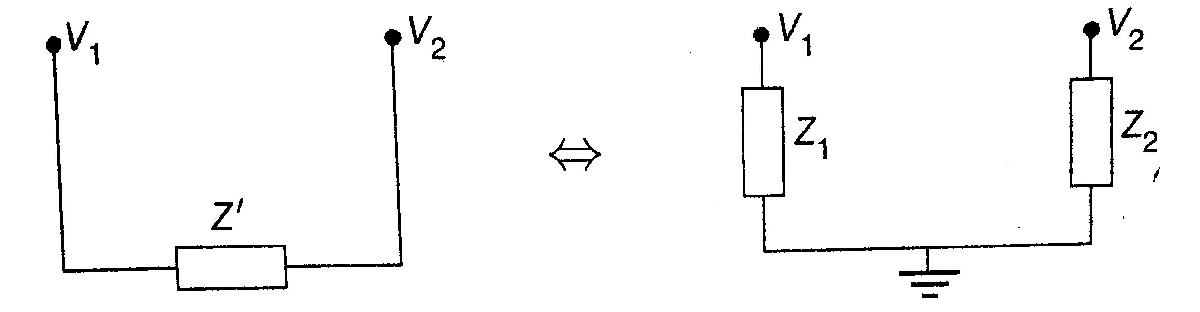

syms Z1 Z2 Z A_v V1 V2
Z1==Z/(1-A_v), Z2==Z/(1-1/A_v), A_v==V2/V1

$$ans = Z_{1}=-\frac{Z}{A_{v}-1}$$

$$ans = Z_{2}=-\frac{Z}{\frac{1}{A_{v}}-1}$$

$$ans = A_{v}=\frac{V_{2}}{V_{1}}$$

**II.**

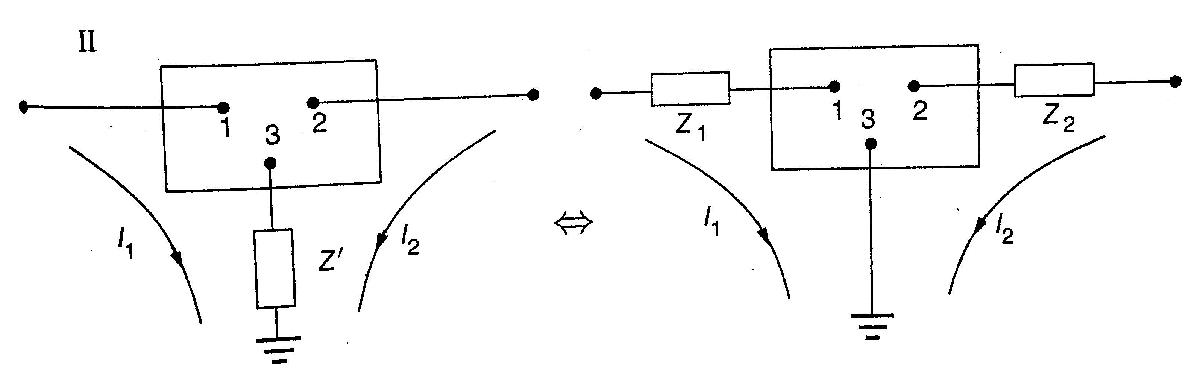

syms A_i I1 I2
Z1==(1-A_i)*Z, Z2==(1-1/A_i)*Z, A_i==I2/I1

$$ans = Z_{1}=-Z\,\left(A_{i}-1\right)$$

$$ans = Z_{2}=-Z\,\left(\frac{1}{A_{i}}-1\right)$$

$$ans = A_{i}=\frac{I_{2}}{I_{1}}$$